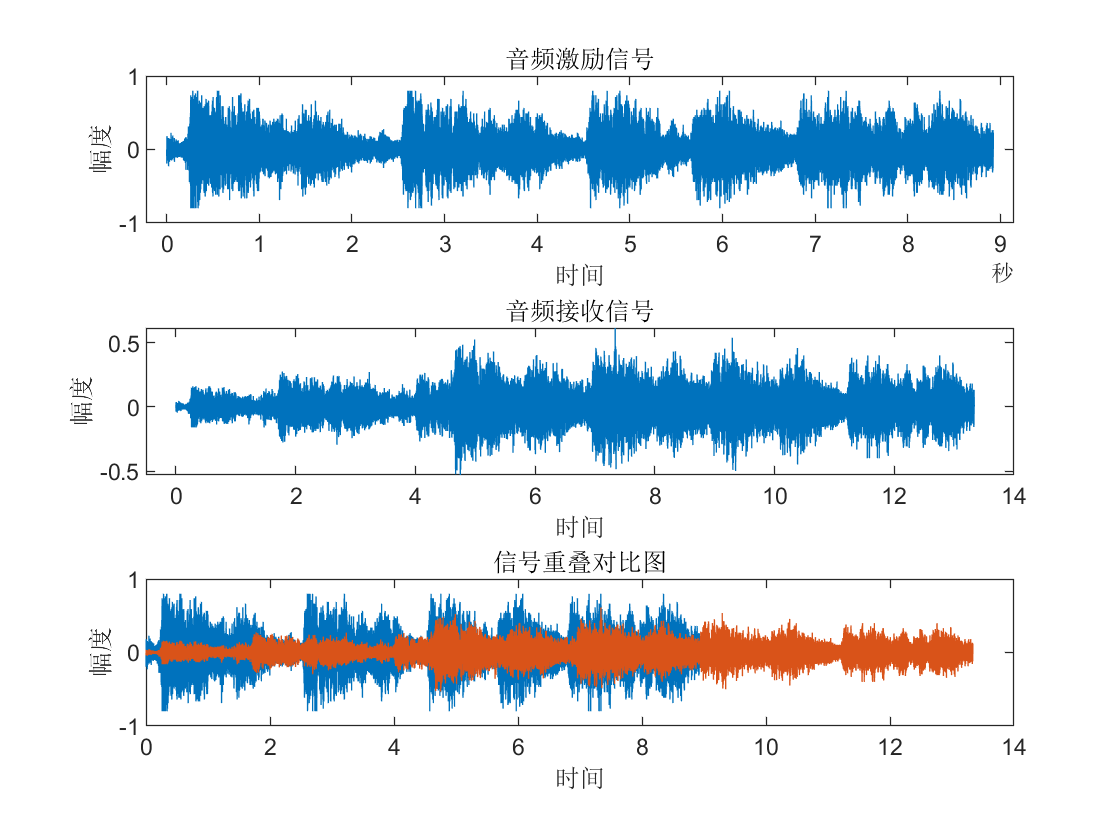

clear;

clc;
[y,Fs] = audioread('handel.wav');%读取音乐

info = audioinfo('handel.wav');%获取音乐信息
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
distance1=500;%第一个障碍物多出的距离为5KM
distance2=1500;%第二个障碍物多出的距离为20KM
v_sound=340;%声音的传播速度340m/s
alpha1=0.2;%第一条信道衰减系数
alpha2=0.3;%第二条信道衰减系数
alpha3=0.5;%第三条信道衰减系数
figure('toolbar','none','menubar','none','PropertyName','音频实验');

subplot(3,1,1);
plot(t,y);
title('音频激励信号');
xlabel('时间');
ylabel('幅度');

f1=y;
f2=[zeros(floor(Fs*distance1/v_sound),1);y];
f3=[zeros(floor(Fs*distance2/v_sound),1);y];
maxsize=max([size(f1,1),size(f2,1),size(f3,1)]);
f=zeros(maxsize,1);
f(1:size(f1,1))=alpha1*f1+f(1:size(f1,1));
f(1:size(f2,1))=alpha2*f2+f(1:size(f2,1));
f(1:size(f3,1))=alpha3*f3+f(1:size(f3,1));

subplot(3,1,2);
x=1:maxsize;
plot(x/Fs,f);
xlim([-0.5, 14]);
title('音频接收信号');
xlabel('时间');
ylabel('幅度');


subplot(3,1,3);
xx=1:info.TotalSamples;

plot(xx/Fs,y);
hold on;
plot(x/Fs,f);
title('信号重叠对比图');
xlabel('时间');
ylabel('幅度');
xlim([-0.5, 14]);

sound(y,Fs);%播放原始音乐
pause(9);%等待9秒使音乐放完
sound(f,Fs);%播放变换过音乐


